## Edge detection using wavelet transformation  

### Sources

[https://www2.humusoft.cz/www/papers/tcb10/078_petrova.pdf](https://www2.humusoft.cz/www/papers/tcb10/078_petrova.pdf)

[https://www.mdpi.com/2076-3417/13/3/1837](https://www.mdpi.com/2076-3417/13/3/1837)

[https://link.springer.com/chapter/10.1007/978-981-13-6504-1_13](https://link.springer.com/chapter/10.1007/978-981-13-6504-1_13)

### Clear

clear all; clc;

### Multiple level wavelet

#### Loading the image 

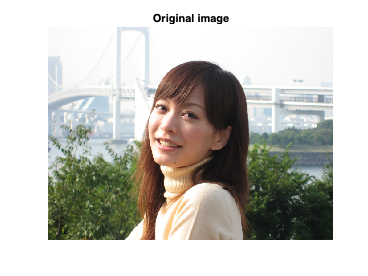

% Path to image
img_path  ='img/cameraman.tif';
img_path  ='img/portrait_5.jpg';

% Original coloured image
original_image = imread(img_path);

imshow(original_image, [], 'InitialMagnification', 'fit'); 
title('Original image'); 

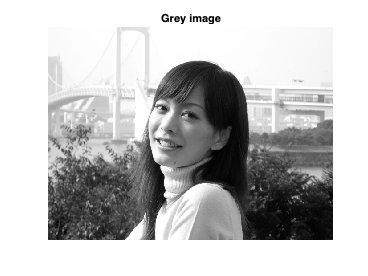


% Convert to greyscale
if size(original_image, 3) == 3
    gray_image = double(rgb2gray(original_image));
else
    gray_image = original_image;
end

imshow(uint8(gray_image), [], 'InitialMagnification', 'fit'); 
title('Grey image'); 

#### Wavelet transform

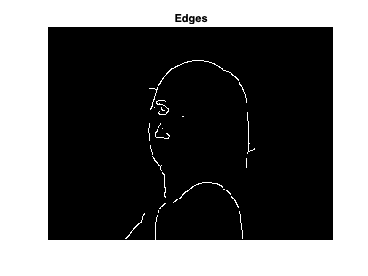

n_levels = 8; % Set the number of levels
wname = 'haar';

% Initialize a cell array to store coefficients at each level
coefficients_cell = cell(n_levels, 1);
temp_gray_image = gray_image/255;

% Perform the wavelet transform for each level and store coefficients
for i = 1:n_levels
    % Perform the wavelet transform
    [cA, cH, cV, cD] = dwt2(temp_gray_image, wname);
    
    if i == 1
        cA = edge(cA, 'Canny', 0.60);
    end
    % Store the coefficients in a cell array
    coefficients_cell{i} = {cA, cH, cV, cD};
    
    % Update the input image for the next level
    temp_gray_image = cA;
end


% Reconstruct the image at each level using the inverse wavelet transform
for i = n_levels:-1:1
    % Retrieve coefficients for the current level
    coefficients_cell_i = coefficients_cell{i};

    cA = coefficients_cell_i{1};
    %cA = zeros(size(cA));

    cH = coefficients_cell_i{2};
    cV = coefficients_cell_i{3};
    cD = coefficients_cell_i{4};

    % Perform the inverse wavelet transform
    reconstructed_level = idwt2(cA, cH, cV, cD, wname);

end

% Binary thresholding
wavelet_threshold = 0.2;
reconstructed_level = reconstructed_level > wavelet_threshold;

% Display the final reconstructed image
imshow(abs(reconstructed_level), [], 'InitialMagnification', 'fit');
title('Edges');

#### Morphological operations

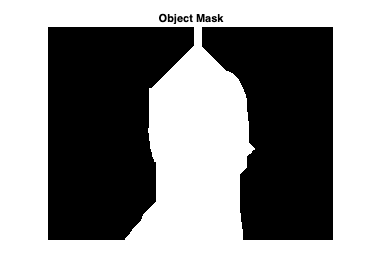

edge_image = reconstructed_level;

% Define a structuring element (disk) for morphological operations
se = strel('disk', 100); % Adjust the size as needed

% Perform morphological dilation to connect edges
% Dilation is an operation that expands or thickens regions in a binary image.
% In this context, it is used to connect nearby edges or gaps in the edgeImage, which can help merge fragmented objects or regions.
dilated_image = imdilate(edge_image, se);

% Perform morphological erosion to refine the object mask
% rosion is an operation that shrinks or erodes regions in a binary image.
% In this context, it is used to refine the object mask by removing any noise 
% or small disconnected regions that may have been introduced during dilation.
object_mask = uint8(imerode(dilated_image, se));

% Invert the object mask to obtain the background mask
background_mask = uint8(~object_mask);

% Display the object mask and background mask
imshow(object_mask, [], 'InitialMagnification', 'fit');
title('Object Mask');

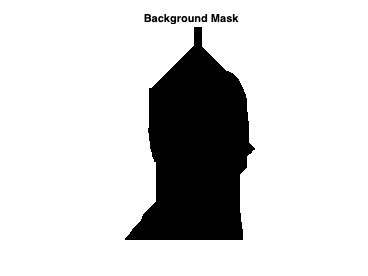


% Display the object mask and background mask
imshow(background_mask, [], 'InitialMagnification', 'fit');
title('Background Mask');

#### Extract mask

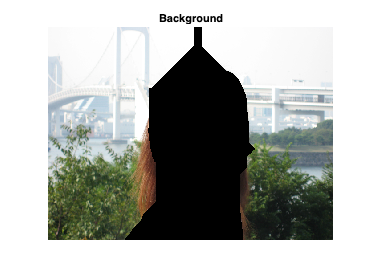

background = background_mask .* original_image;
object = object_mask .* original_image;

imshow(background, [], 'InitialMagnification', 'fit');
title('Background')

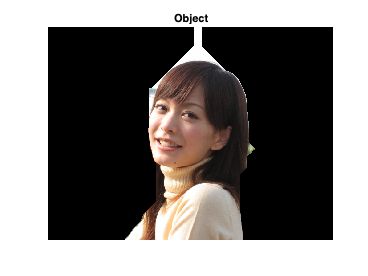


imshow(object, [], 'InitialMagnification', 'fit');
title('Object')

#### Object enhancement 

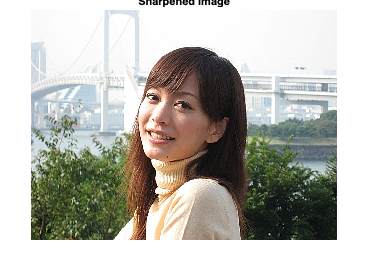

% Step 2: Sharpening
% You can adjust the 'amount' and 'radius' parameters for desired sharpening
sharpened = imsharpen(original_image, 'Amount', 2, 'Radius', 1);

% Display the sharpened image
figure;
imshow(sharpened);
title('Sharpened Image');

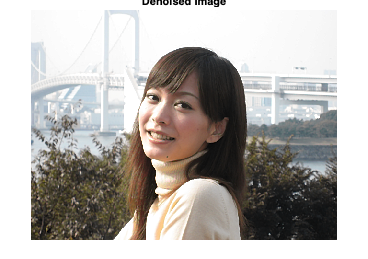


% Step 3: Noise Reduction (e.g., Median Filtering)
% Adjust the 'windowSize' parameter for the desired filter size
windowSize = 3; % Adjust the filter size
denoisedImage = medfilt3(sharpened);

% Display the denoised image
figure;
imshow(denoisedImage);
title('Denoised Image');

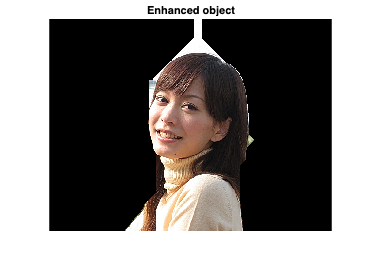


enhanced_object = sharpened .* object_mask;
imshow(enhanced_object, [], 'InitialMagnification', 'fit');
title('Enhanced object')

#### Background blur 

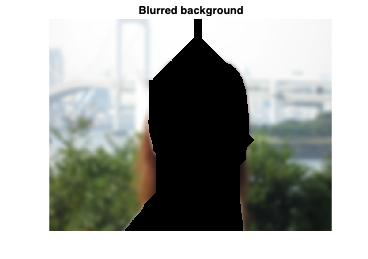

sigma = 5;
blurred_background = imgaussfilt(sharpened, sigma) .* background_mask; 
imshow(blurred_background, [], 'InitialMagnification', 'fit');
title('Blurred background')

#### Final results

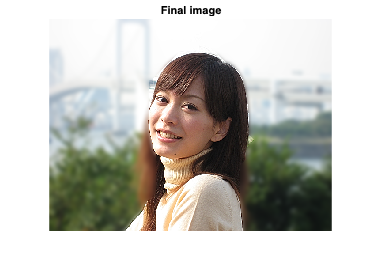

final_image = blurred_background + enhanced_object;
imshow(final_image, [], 'InitialMagnification', 'fit');
title('Final image')